grid = gen_grid();
N = 5000;
seed = 100;
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000, seed, "Cirkel");
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)) ; zeros(1,length(data_XA)) ones(1,length(data_XB))];
networks = metropolis_hasting([2 5 2], N, 0.29, 14, data, seed);

burned = 0.0393

iterations = 0.0195

resultNetworks = cell(1,N/20);
indexes = randperm(N,N/10);
for ind = 1:length(indexes)
     resultNetworks{1,ind} = networks{1,indexes(ind)}; 
end


% Uncertainty plotter
% cell(1,n) = x_co
% cell(2,n) = y_co
% cell(3,n) = uncertainty
x_vec = cell(1,length(grid));
y_vec = cell(1,length(grid));
uncert_color = [];

class_vec = [];

% Classify all data points and assign unceratinty
for i = 1:length(grid)
    x = [grid(1,i); grid(2,i)];
    out = bayesian_classify(x, resultNetworks);
    x_vec{1,i} = grid(1,i);
    y_vec{1,i} = grid(2,i);
    u = abs(out(1)-out(2));
    class_vec = [class_vec;u];
    base = [0.5 0.1 0];
    r =    [0.5*u 0 0];
    g =    [0 0.7*u-0.3 0];
    uncert_color = [uncert_color; (base + r + g)];
end

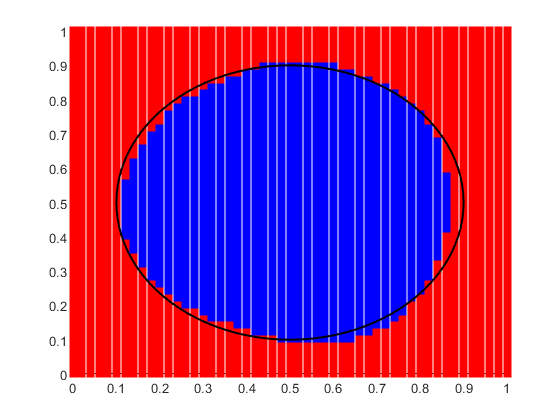

grid = gen_grid();
corClass = correct_classify_circle(grid);
cor_counter = 0;

XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = bayesian_classify(x,resultNetworks);
    if probs(1) >= probs(2)
        XA = [XA, grid(1,c)];
        YA = [YA, grid(2,c)];
        if corClass{c} == "A"
                cor_counter = cor_counter + 1;
        end
    else
        XB = [XB, grid(1,c)];
        YB = [YB, grid(2,c)];
        if corClass{c} == "B"
                cor_counter = cor_counter + 1;
        end
    end
end

XA = cell2mat(XA);
YA = cell2mat(YA);
XB = cell2mat(XB);
YB = cell2mat(YB);

th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;


    
figure
hold on
axis([0 1 0 1])
scatter(XA,YA,80,'blue','filled','s')
scatter(XB,YB,80,'red','filled','s')
plot(xunit,yunit,'black','LineWidth',1.5);
hold off


percentage_correct = (cor_counter/length(grid)) * 100

percentage_correct = 96.6167

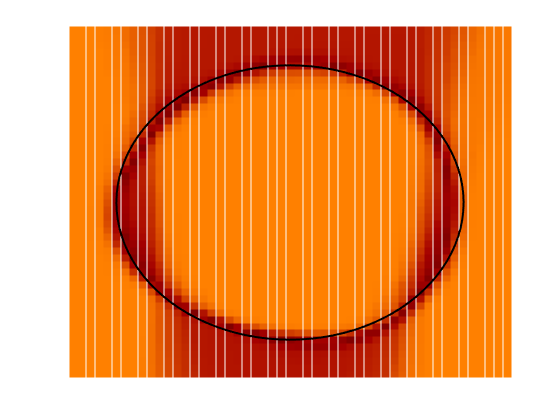

% Plot uncertaintys using a color gradient
figure
hold on
axis([0 1 0 1])

x_vec = cell2mat(x_vec);
y_vec = cell2mat(y_vec);
scatter(x_vec,y_vec,80,uncert_color,'filled','s')

th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;
plot(xunit,yunit,'black','LineWidth',1.5);

color = 'none';
set(gca,'XColor',color,'YColor',color,'TickDir','out')

hold off

% Accept only classifications that are made with a given confidence
confidence = 0.7;

grid = gen_grid();
corClass = correct_classify_circle(grid);
error_counter = 0;

XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = bayesian_classify(x,resultNetworks);
    if probs(1) >= probs(2)
        XA = [XA, grid(1,c)];
        YA = [YA, grid(2,c)];
        if corClass{c} == "B" && probs(1) > confidence
                error_counter = error_counter + 1;
        end
    else
        XB = [XB, grid(1,c)];
        YB = [YB, grid(2,c)];
        if corClass{c} == "A" && probs(2) > confidence
                error_counter = error_counter + 1;
        end
    end
end

percentage_wrong = (error_counter/length(grid)) * 100

percentage_wrong = 0.6151

% Real research starts here

confidence = 0.8;

error_percents = [];

for seed= 2000:100:3000
   [data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000, seed, "Cirkel");
   data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)); zeros(1,length(data_XA)) ones(1,length(data_XB))];
    
   % initialize grid and variables
   grid = gen_grid();
   corClass = correct_classify_circle(grid);
   
   % data to draw circle
    th = 0:pi/50:2*pi;
    xunit = 0.4 * cos(th) + 0.5;
    yunit = 0.4 * sin(th) + 0.5;
    
   % parameters
   iterations = 500;
   network = [2 5 2];
   q_sigma = 0.25;
   reg_sigma = 10;
   
   for i = 1:1 % placeholder loop
       networks = metropolis_hasting(network, iterations, q_sigma, reg_sigma, data, seed);
       
       resultNetworks = cell(1,100);
       indexes = randperm(iterations,100);
       for ind = 1:length(indexes)
           resultNetworks{1,ind} = networks{1,indexes(ind)};
       end
       
       error_counter = 0;
       
       XA = {};
       YA = {};
       XB = {};
       YB = {};
       
       for c = 1:length(grid)
           x = [grid(1,c); grid(2,c)];
           probs = bayesian_classify(x,resultNetworks);
           if probs(1) >= probs(2)
               XA = [XA, grid(1,c)];
               YA = [YA, grid(2,c)];
               if corClass{c} == "B" && probs(1) > confidence
                   error_counter = error_counter + 1;
               end
           else
               XB = [XB, grid(1,c)];
               YB = [YB, grid(2,c)];
               if corClass{c} == "A" && probs(2) > confidence
                   error_counter = error_counter + 1;
               end
           end
       end
       
       percentage_wrong = (error_counter/length(grid)) * 100;
       error_percents = [error_percents percentage_wrong];    
   end
end

burned = 0.2094

iterations = 0.1147

burned = 0.2217

iterations = 0.1384

burned = 0.2222

iterations = 0.1129

burned = 0.1916

iterations = 0.1881

burned = 0.6211

iterations = 0.3891

burned = 0.3690

iterations = 0.2943

burned = 0.6061

iterations = 0.5834

burned = 0.6289

iterations = 0.9542

burned = 0.0588

iterations = 0.0428

burned = 0.6410

iterations = 0.9524

burned = 0.1998

iterations = 0.2732

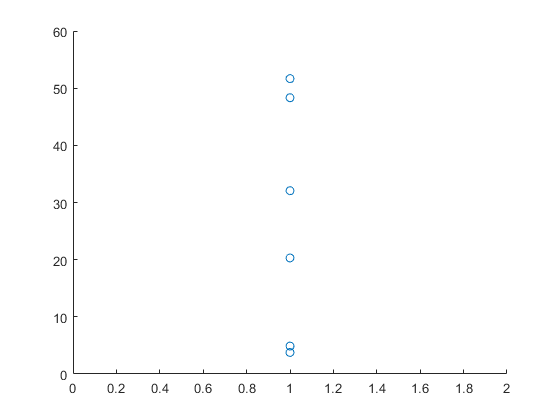

%plot results

scatter([1 1 1 1 1 1 1 1 1 1 1], error_percents)